Generate gyroscope data for an imuSensor object from stationary inputs.

clc
clear
% params = gyroparams('MeasurementRange',4.363,'Resolution',1.332e-04,'ConstantBias',0.349);
% params = gyroparams('MeasurementRange',4.363,'Resolution',1.332e-04,'ConstantBias',[0.349 0.249 0.149]);
constant_bias = [1 2 3];
params = gyroparams('MeasurementRange',4.363,'Resolution',1.332e-04,'ConstantBias',constant_bias, ...
    'BiasInstability',[0.1 0.2 0.3]);

Use a sample rate of 100 Hz spaced out over 1000 samples. Create the imuSensor object using the gyroscope parameter object.

Fs = 100;
numSamples = 10000;
t = 0:1/Fs:(numSamples-1)/Fs;

imu = imuSensor('accel-gyro','SampleRate', Fs, 'Gyroscope', params);

Generate gyroscope data from the imuSensor object.

orient = quaternion.ones(numSamples, 1);
acc = zeros(numSamples, 3);
angvel = zeros(numSamples, 3);
 
[~, gyroData] = imu(acc, angvel, orient);

Plot the resultant gyroscope data.

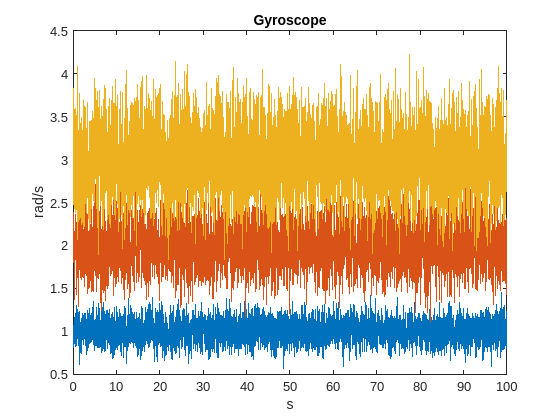

plot(t, gyroData)
title('Gyroscope')
xlabel('s')
ylabel('rad/s')

Calculate the bias instability

% Find Bias Instability
biasInstability = std(gyroData);

disp(['Bias Instability: ', num2str(biasInstability), ' rad/s']);

Bias Instability: 0.11556     0.22908     0.34564 rad/s
